# Experiment 3

This Live Script contains the experimental setup for the section *"Boosting the three-phase features of Matpower"*  included in the draft paper:

**"A Quadratic Approximation of AC Power Flows in Transformed Polar Coordinates" **

by Wilson Gonzalez-Vanegas and Carlos E. Murillo-Sanchez

Submitted on 29-jun-2025 for consideration in the journal:

 [e-Prime - Advances in Electrical Engineering, Electronics and Energy](https://www.sciencedirect.com/journal/e-prime-advances-in-electrical-engineering-electronics-and-energy)

*Notes: *

- *MATLAB R2023a is the oldest version where this Live Script was successfully tested.*

- *This script requires the class *`mp.case_utils.convert_1p_to_3p `which is currently available in the latest GitHub version of Matpower. See [merged commits](https://github.com/MATPOWER/matpower/pull/268) for more information.

We start by loading the IEEE 39-bus test case and then convert it using the `convert_1p_to_3p` function:

mpc1p = loadcase('case39')

mpc1p = struct with fields:
    version: '2'
    baseMVA: 100
        bus: [39×13 double]
        gen: [10×21 double]
     branch: [46×13 double]
    gencost: [10×7 double]


mpc3p = mp.case_utils.convert_1p_to_3p(mpc1p)

mpc3p = struct with fields:
    version: '2'
    baseMVA: 100
        bus: []
        gen: []
     branch: []
    gencost: []
       freq: 60
    basekVA: 100000
      bus3p: [39×9 double]
     line3p: [34×6 double]
     xfmr3p: [12×9 double]
    shunt3p: []
     load3p: [21×9 double]
      gen3p: [10×12 double]
         lc: [34×19 double]
    buslink: []


Now, we run a power flow over the balanced three-phase equivalent of the network:

mpopt = mpoption('verbose',3);
res_bal = run_pf(mpc3p,mpopt,'mpx',mp.xt_3p);


MATPOWER Version 8.1-dev, 04-Jul-2025
Power Flow -- AC-polar-power formulation

 it    max residual        max ∆x
----  --------------  --------------
  0      9.684e-06           -    
  1      3.464e-13       4.799e-08
Newton's method converged in 1 iterations.
PF successful

PF succeeded in 0.27 seconds (0.25 setup + 0.01 solve)
|     System Summary                                                           |
  elements                on     off    total
 --------------------- ------- ------- -------
  3-ph Buses               39       -      39
  3-ph Generators          10       -      10
  3-ph Loads               21       -      21
  3-ph Lines               34       -      34
  3-ph Transformers        12       -      12

  Total 3-ph generation            6297871.1 kW    1274939.0 kVAr
  Total 3-ph load               

Then, we unbalance all the loads by introducing small random changes to the power factors drawn from a normal distribution between 0.5 and 1.5:

noisefac = [ 1.36         1.17         1.31
             0.78         1.43         1.43
             1.00         1.03         0.70
             1.31         1.31         1.31
             1.43         0.82         0.99
             1.47         1.01         1.30
             1.46         0.90         0.96
             0.79         0.69         0.68
             0.88         1.10         1.25
             0.83         0.65         0.91
             0.95         1.35         0.75
             1.48         1.01         1.29
             0.74         1.29         1.47
             0.83         0.50         1.34
             0.78         1.40         0.72
             0.52         0.58         0.75
             0.71         0.67         0.51
             1.06         0.74         0.52
             1.43         0.69         0.54
             1.09         0.87         1.00
             1.31         0.99         1.43];
         
mpc3p.load3p(:,[7 8 9]) = noisefac .* mpc3p.load3p(:,[7 8 9]);

Hence, we can run a power flow over this unbalanced network:

res_unbal = run_pf(mpc3p,mpopt,'mpx',mp.xt_3p);


MATPOWER Version 8.1-dev, 04-Jul-2025
Power Flow -- AC-polar-power formulation

 it    max residual        max ∆x
----  --------------  --------------
  0      2.565e+00           -    
  1      1.518e+00       8.280e-01
  2      8.409e-02       6.168e-02
  3      3.255e-04       5.268e-03
  4      1.713e-08       4.419e-05
  5      4.219e-14       2.639e-09
Newton's method converged in 5 iterations.
PF successful

PF succeeded in 0.23 seconds (0.19 setup + 0.04 solve)
|     System Summary                                                           |
  elements                on     off    total
 --------------------- ------- ------- -------
  3-ph Buses               39       -      39
  3-ph Generators          10       -      10
  3-ph Loads               21       -      21
  3-ph Lines               34       -      34
  3-p

Finally, we can compare the results. We show, for instance, active power injected at the from end of the transformer connected at the reference bus, and voltages in bus 16, which is the one with the largest number of connected branches:

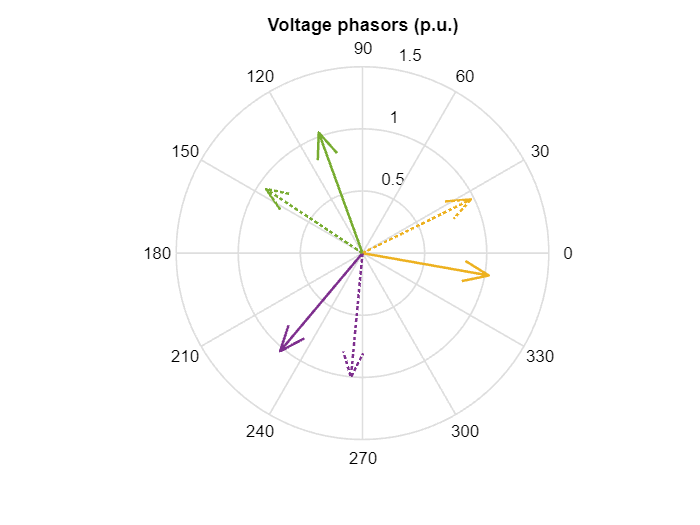

idbus = 16;

va_bal_a = res_bal.dm.elements.bus3p.tab.va1(idbus);
va_bal_b = res_bal.dm.elements.bus3p.tab.va2(idbus);
va_bal_c = res_bal.dm.elements.bus3p.tab.va3(idbus);
vm_bal_a = res_bal.dm.elements.bus3p.tab.vm1(idbus);
vm_bal_b = res_bal.dm.elements.bus3p.tab.vm2(idbus);
vm_bal_c = res_bal.dm.elements.bus3p.tab.vm3(idbus);

va_unbal_a = res_unbal.dm.elements.bus3p.tab.va1(idbus);
va_unbal_b = res_unbal.dm.elements.bus3p.tab.va2(idbus);
va_unbal_c = res_unbal.dm.elements.bus3p.tab.va3(idbus);
vm_unbal_a = res_unbal.dm.elements.bus3p.tab.vm1(idbus);
vm_unbal_b = res_unbal.dm.elements.bus3p.tab.vm2(idbus);
vm_unbal_c = res_unbal.dm.elements.bus3p.tab.vm3(idbus);

[x_bal,y_bal] = pol2cart(deg2rad([va_bal_a; va_bal_b; va_bal_c]), [vm_bal_a; vm_bal_b; vm_bal_c]);
[x_unbal,y_unbal] = pol2cart(deg2rad([va_unbal_a; va_unbal_b; va_unbal_c]), [vm_unbal_a; vm_unbal_b; vm_unbal_c]);

figure;
pp1 = compass(x_bal,y_bal);
pp1(1).LineWidth = 1.5;
pp1(2).LineWidth = 1.5;
pp1(3).LineWidth = 1.5;
pp1(1).Color = [0.929 0.694 0.125];
pp1(2).Color = [0.494 0.184 0.556];
pp1(3).Color = [0.466 0.674 0.188];
hold on
pp2 = compass(x_unbal,y_unbal);
pp2(1).LineWidth = 1.5;
pp2(2).LineWidth = 1.5;
pp2(3).LineWidth = 1.5;
pp2(1).Color = [0.929 0.694 0.125];
pp2(2).Color = [0.494 0.184 0.556];
pp2(3).Color = [0.466 0.674 0.188];
pp2(1).LineStyle = ':';
pp2(2).LineStyle = ':';
pp2(3).LineStyle = ':';
title('Voltage phasors (p.u.)')

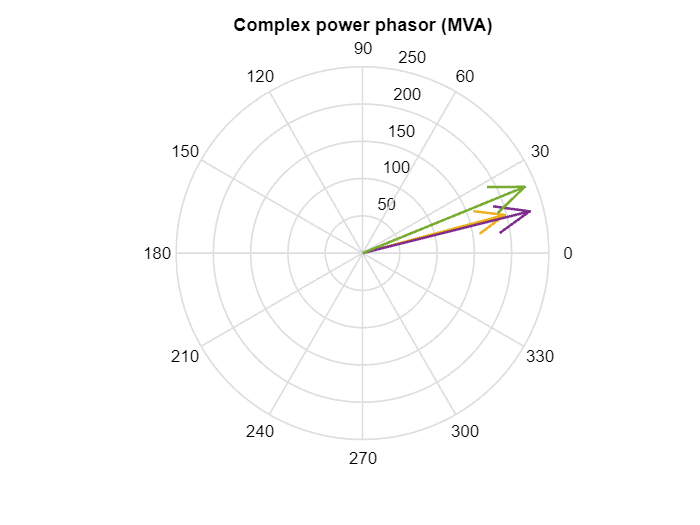


id_line = 27;

x_unbal = [res_unbal.dm.elements.line3p.tab.pl1_fr(id_line)
           res_unbal.dm.elements.line3p.tab.pl2_fr(id_line)
           res_unbal.dm.elements.line3p.tab.pl3_fr(id_line)]*1e-3;
y_unbal = [res_unbal.dm.elements.line3p.tab.ql1_fr(id_line)
           res_unbal.dm.elements.line3p.tab.ql2_fr(id_line)
           res_unbal.dm.elements.line3p.tab.ql3_fr(id_line)]*1e-3;

figure;
pp3 = compass(-1*x_unbal, -1*y_unbal);
pp3(1).LineWidth = 1.5;
pp3(2).LineWidth = 1.5;
pp3(3).LineWidth = 1.5;
pp3(1).Color = [0.929 0.694 0.125];
pp3(2).Color = [0.494 0.184 0.556];
pp3(3).Color = [0.466 0.674 0.188];
title('Complex power phasors (MVA)')